# The Heat Equation

# 1.1


$$c\left(x,t,u,\frac{\partial u}{\partial x}\right)\frac{\partial u}{\partial t}=x^{-m} \frac{\partial }{\partial x}\left(x^m f\left(x,t,u,\frac{\partial u}{\partial x}\right)\right)+s\left(x,t,u,\frac{\partial u}{\partial x}\right)\ldotp$$


In this form, the heat equation is:


$$50\cdot \frac{\partial u}{\partial t}=x^0 \frac{\partial }{\partial x}\left(x^0 \frac{\partial u}{\partial x}\right)+0\ldotp$$


So the values of the coefficients are as follows:

- 
$$m=0$$


- 
$$c=50$$


- 
$$f=\frac{\partial u}{\partial x}$$


- 
$$s=0$$


# 1.2

## Initial Condition

The initial condition function for would be as follows:

as it is obvious we should assign $u\left(x,0\right)\;\;\mathrm{to}\;\;2e^x$.

# 1.3

## Boundary Conditions

The standard form for the boundary conditions is


$$p\left(x,t,u\right)+q\left(x,t\right)f\left(x,t,u,\frac{\partial u}{\partial x}\right)=0\ldotp$$


the values for $p$ and $q$ are

- *left BC: *  $p_L =u_L -0,{\;\;\;\;\;\;\;\;\;\;\;\;\;q}_L =0\ldotp$

- *right BC:*   $p_R =u_R -50,{\;\;\;\;\;q}_R =0$.

# 1.4

## Solving pde

L = 2;
x = linspace(0,L,200);
t = linspace(0,10,201);
m = 0;
solution = pdepe(m,@pde,@ic,@bc,x,t);

# 1.5

## Temperture In Different Times

solution is a 3-d array as follows:

($t_i \;,x_j \;,u_k$) 

so if we trying to reach the solution in a specific time we should put that second index in first position.

so for $t=0$ the index would be ($1\;,:\;,\;:\;$) 

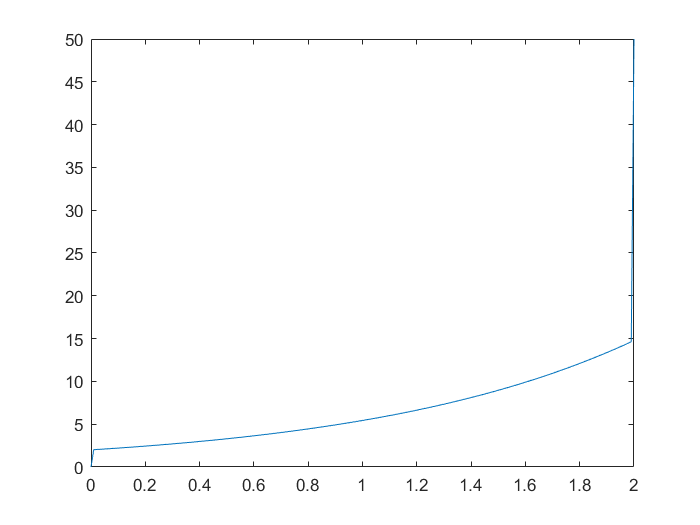

plot(x,solution(1,:,:));

for $t=5$ the index would be ($101\;,:\;,\;:\;$) 

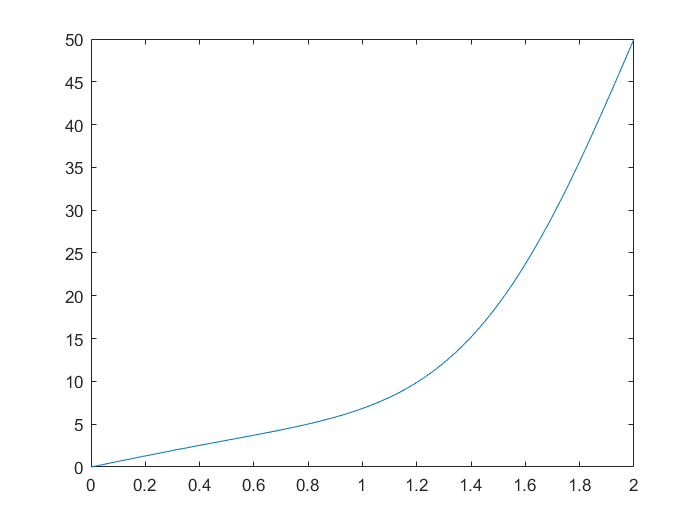

plot(x,solution(101,:,:));

for $t=10$ the index would be ($201\;,:\;,\;:\;$) 

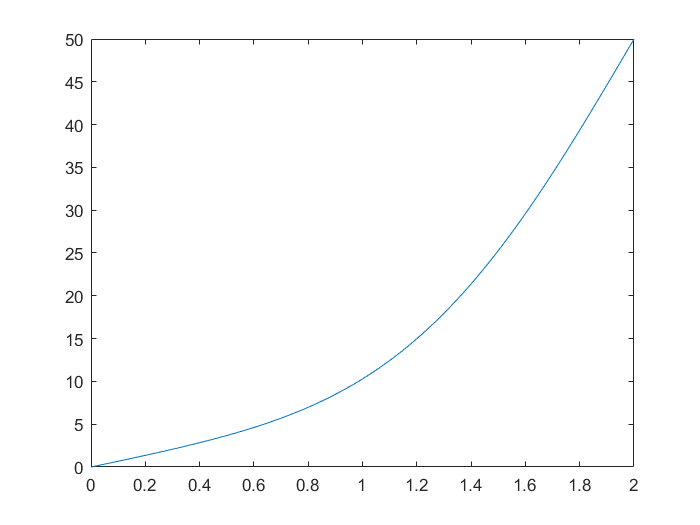

plot(x,solution(201,:,:));

- as we can see the heat on right end stays the same because the source of constant energy is at the right end

- by passing time heat conducts to left and causes the middle parts to become hotter

- because the time range is not that big we see more impact on parts that are closer to source

- because of the heat conduction as time passes the heat plot gets closer to linear form

## Plot Solution

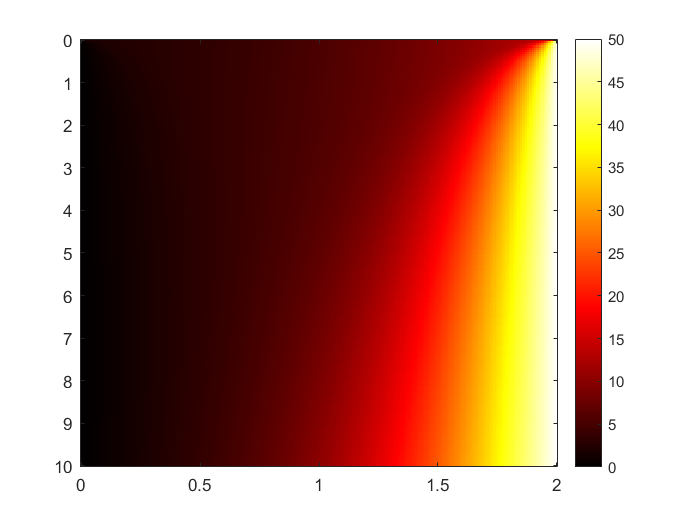

imagesc(x,t,solution)
colormap hot
colorbar

- *as it is obvious as the time goes on more heat will conduct from right end of bar towards left*

- *because of constant energy source on right end the temperture on right side stays the same *

- *du/dx is ascending because as it is obvious in plot as we go furthur in x the temperture goes higher*

## 3D Figure

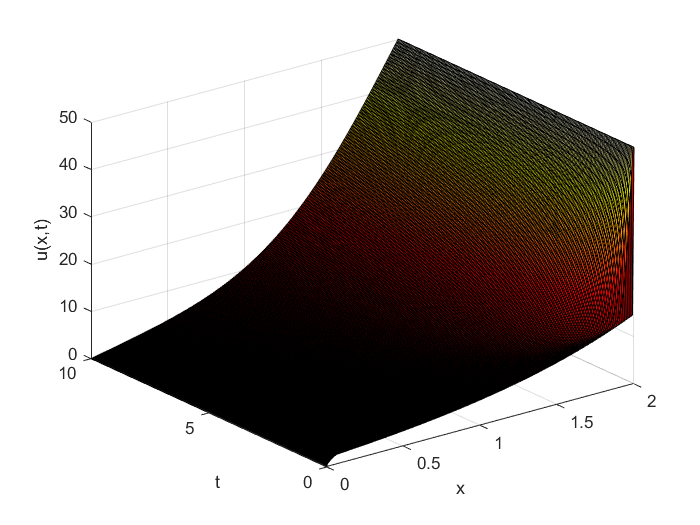

surf(x,t,solution);
xlabel('x')
ylabel('t')
zlabel('u(x,t)')

## Solving Pde For New Range Of t And x

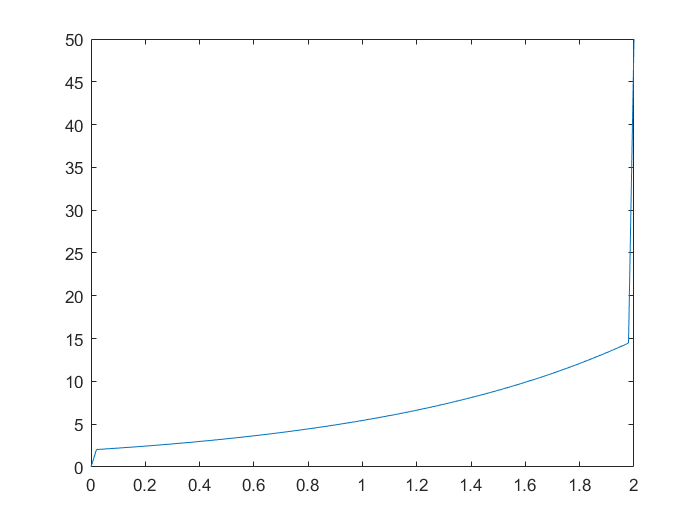

L = 2;
x = linspace(0,L,100);
t = linspace(0,10,101);
m = 0;
solution = pdepe(m,@pde,@ic,@bc,x,t);

plot(x,solution(1,:,:));

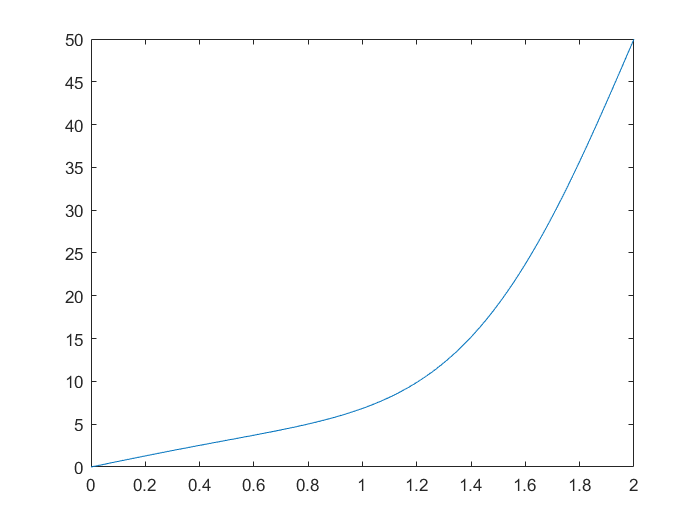

plot(x,solution(51,:,:));

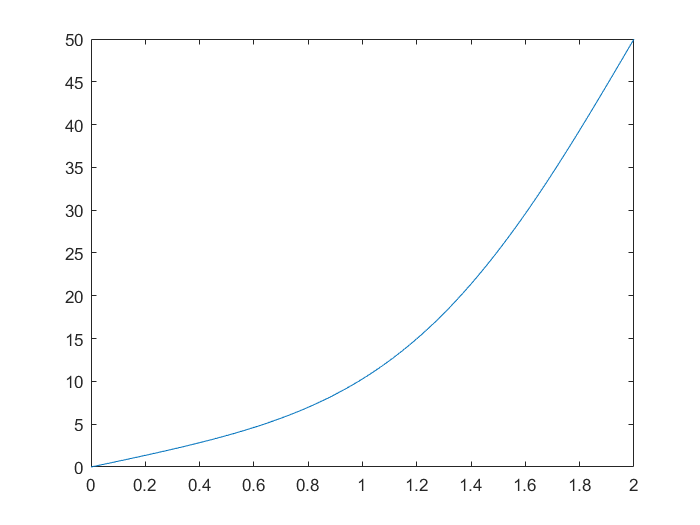

plot(x,solution(101,:,:));

most of the results are the same and didn't change from prevoius range for x and t but because of decreasing the accuracy the plots are more round.

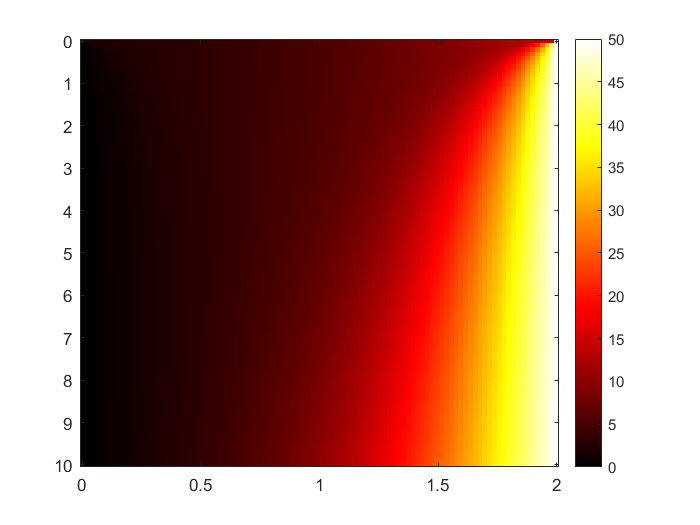

imagesc(x,t,solution)
colormap hot
colorbar

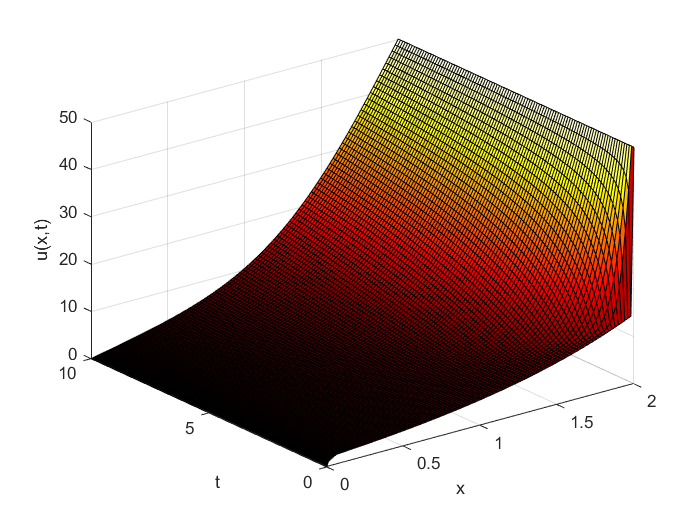


surf(x,t,solution);
xlabel('x')
ylabel('t')
zlabel('u(x,t)')

because of decreasing the accuracy the plots are less percise.

# Local Functions

function [c,f,s] = pde(x,t,u,dudx)
c = 50;
f = dudx;
s = 0;
end
function u0 = ic(x)
u0 = 2*exp(x);
end
function [pl,ql,pr,qr] = bc(xl,ul,xr,ur,t)
pl = ul;
ql = 0;
pr = ur - 50;
qr = 0;
end